# SVM MODEL TRAINING (STEP 1)

clear; clc; close all

## load TrainING data

DATA FORMAT: 

- exp_dat_raw : numeric ( m x n)

- class_label : label (1 xn)

- gene_names : variable name (m x 1)


filename=strcat('Explant_ResponseGroup_Allprot_DEGs.xlsx');
tbl_PDE_dat=readtable(filename,...
    'Sheet','DEG expression');
tbl_PDE_label=readtable(filename,...
    'Sheet','Target labels');
tbl_PDE_dat.GeneName(ismember(tbl_PDE_dat.GeneName,{'SEPTIN8'}))= {'SEPT8'};



for ss = 1:100
    disp(ss)
    rng(ss)
    rand_samp = randsample(size(tbl_PDE_dat,1),16);
    
    exp_dat_raw=table2array(tbl_PDE_dat(rand_samp,2:end));
    class_label = table2array(tbl_PDE_label);
    gene_names = tbl_PDE_dat.GeneName(rand_samp);
    model_name = '';
    
    %% Training data normalization between 0 and 1
    tmp_min = repmat(min(exp_dat_raw')',1,size(exp_dat_raw,2));
    tmp_max = repmat(max(exp_dat_raw')',1,size(exp_dat_raw,2));
    predictor = (exp_dat_raw -  tmp_min)./(tmp_max - tmp_min);
    
    %% RUN THE SIMULATION
    no_cross_val = 50;
    no_samples = size(predictor,2);
    
    %% Rrandom sampling for train (80%) and test (20%)
    for ii = 1:no_cross_val
        rng(ii); % random number seed for reproducibility
        [train_sample_idx(ii,:),~,test_sample_idx(ii,:)] = dividerand(no_samples,0.8,0.0,0.2);
    end
    
    %% training the models
    
    
    parfor  idx1 = 1:no_cross_val
        
        %disp(idx1)
        
        % copy variables for parfor
        predictor_par = predictor;
        class_label_par = class_label;
        train_sample_idx_par = train_sample_idx;
        test_sample_idx_par = test_sample_idx;
        
        % random sampling for training an test
        train_idx = train_sample_idx_par(idx1,:);
        test_idx = test_sample_idx_par(idx1,:);
        
        % Train & Test data
        predictor_train = predictor_par(:,train_idx); % training input
        predictor_test = predictor_par(:,test_idx); % test input
        
        class_label_train = class_label_par(train_idx);
        class_label_true_compiled(:,idx1) = class_label_par(test_idx);
        
        rng(idx1);
        
        % SVM options
        svmtemp=templateSVM('Standardize',1,...
            'KernelFunction','linear');
        Mdl = fitcecoc(predictor_train',class_label_train',...
            'Learners',svmtemp,...
            'ClassNames',{'NR', 'RD','PR'});
        class_label_pred_compiled(:,idx1) = predict(Mdl,predictor_test');
        
        % to plot the ROC curve
        Mdl2 = fitcecoc(predictor_train',class_label_train',...
            'Learners',svmtemp,...
            'ClassNames',{'NR', 'RD','PR'},...
            'FitPosterior',true);
        [class_label_pred_compiled2(:,idx1),~,~,cnum2(:,:,idx1)]=predict(Mdl2,predictor_test');
        
        % save the Models for validation
        trained_Mdl{idx1} = Mdl;
    end
    
    % fpath = strcat(pwd,'\data.validation\Mdl_',model_name,'.mat');
    % save(fpath,'trained_Mdl');
    
    %% Post-processing
    
    for idx1 = 1:no_cross_val
        
        [cmat,~] = confusionmat(class_label_true_compiled(:,idx1),class_label_pred_compiled(:,idx1));
        score_mat(idx1)= sum(diag(cmat)/length(class_label_true_compiled(:,idx1)));
        
    end
    
    % averaged prediction accuracy
    avg_prediction_acc = mean(score_mat);
    disp(strcat('Prediction = ',num2str(avg_prediction_acc)))
        
    pred_acc(ss) = mean(score_mat);
    
end

Prediction =0.4825
Prediction =0.6075
Prediction =0.565
Prediction =0.57
Prediction =0.6725
Prediction =0.73
Prediction =0.5025
Prediction =0.5675
Prediction =0.5475
Prediction =0.6
Prediction =0.515
Prediction =0.685
Prediction =0.5425
Prediction =0.54
Prediction =0.605
Prediction =0.5375
Prediction =0.6075
Prediction =0.7175
Prediction =0.4575
Prediction =0.55
Prediction =0.6125
Prediction =0.5525
Prediction =0.615
Prediction =0.6525
Prediction =0.67
Prediction =0.59
Prediction =0.6
Prediction =0.51
Prediction =0.5525
Prediction =0.62
Prediction =0.5025
Prediction =0.59
Prediction =0.5725
Prediction =0.5875
Prediction =0.66
Prediction =0.58
Prediction =0.6075
Prediction =0.4475
Prediction =0.6625
Prediction =0.5725
Prediction =0.635
Prediction =0.5275
Prediction =0.6775
Prediction =0.6275
Prediction =0.615
Prediction =0.57
Prediction =0.5875
Prediction =0.575
Prediction =0.505
Prediction =0.585
Prediction =0.61
Prediction =0.5775
Prediction =0.5725
Prediction =0.6475
Prediction =0.59

## Plot a distribution of curve for prediction accuracy

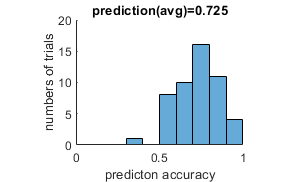

figure('Position',[680   796   308   182])
edges = [0:0.1:1];
histogram(pred_acc,edges)
title(strcat('prediction(avg)=',num2str(mean(pred_acc))))
xlabel('predicton accuracy'),ylabel('numbers of trials')
pbaspect([4 3 1]/4)
box off


figure, boxchart(pred_acc,'Notch','on')
tbl_pred = table(pred_acc');

tbl_pred = 50×1 table
    Var1 
    _____

     0.75
      0.5
     0.75
    0.875
        1
    0.625
      0.5
      0.5
    0.625
    0.625
    0.875
        1
    0.625
     0.75
    0.875
     0.75


summary(tbl_pred)


finename=strcat(pwd,'\data.output\validation of the selected 16 features.csv');
writetable(tbl_pred,finename);

